# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\RawData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Folder.Version     = ['C:\Users\User\Desktop\Zeng\Newstruz\Instru\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)                                                           % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)
                                                                   % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

Deci.Analysis.Conditions    = {[21 31 51] [23 31 51] [21 31 52] [23 31 52] ...
                               [21 32 51] [23 32 51] [21 32 52] [23 32 52]};
Deci.Analysis.CondTitle     = {'Opt AB Corr' 'Opt CD Corr' ...
                               'Opt AB Inc'  'Opt CD Inc' ...
                               'Wst AB Corr' 'Wst CD Corr' ...
                               'Wst AB Inc'  'Wst CD Inc' };

## 5. Plotting

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Figure = [false true];
Deci.Plot.Behv.Acc.Total = {{[1:16] [1:16]} {[1 5 9 13] [2 6 10 14] [3 7 11 15] [4 8 12 16]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1:8] [9:16]} {[1 5] [2 6] [3 7] [4 8]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {{'Opt Percent' 'Wst Percent'} {'AB' 'CD' 'EF' 'GH'}};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;


Deci.Plot.Behv.RT.Figure = [false true];
Deci.Plot.Behv.RT.Draw = {{[1:8] [9:16]}  {[1 5] [2 6] [3 7] [4 8] [9 13] [10 14] [11 15] [12 16]}};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials RT'};
Deci.Plot.Behv.RT.Subtitle = {{'Opt' 'Worst'} {'Opt AB' 'Opt CD' 'Opt EF' 'Opt GH' 'Wst AB' 'Wst CD' 'Wst EF' 'Wst GH'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

Deci.Plot.Extra.List = false;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

Options

Deci.Run.Behavior = true;

## ** 6. Run**

ans = struct with fields:
         Folder: [1×1 struct]
    SubjectList: {'Instru_EEG_011'  'Instru_EEG_013'  'Instru_EEG_014'  'Instru_EEG_017'  'Instru_EEG_018'  'Instru_EEG_019'  'Instru_EEG_026'  'Instru_EEG_032'  'Instru_EEG_044'}
           Step: 5
             DT: [1×1 struct]
       Analysis: [1×1 struct]
           Plot: [1×1 struct]
            Run: [1×1 struct]
         Layout: [1×1 struct]
        Proceed: 0
          Debug: 0


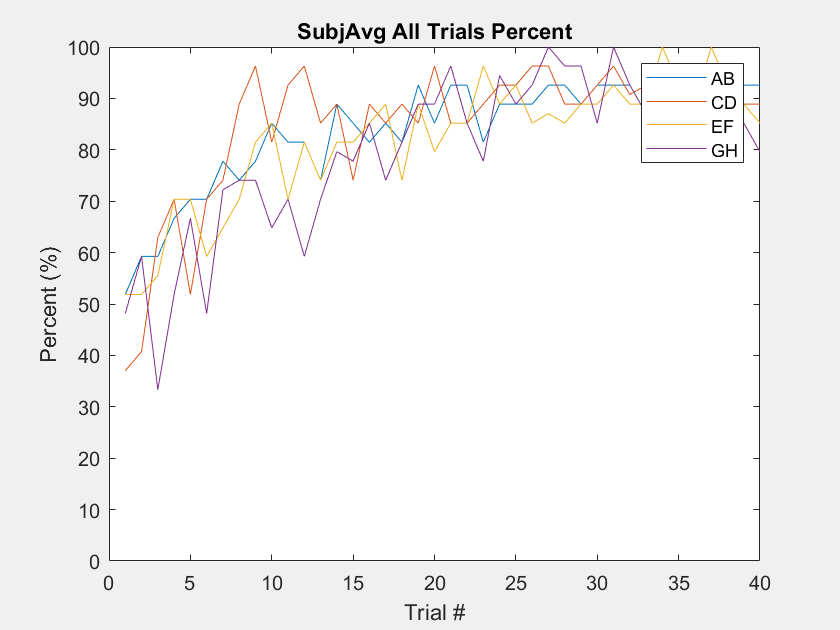

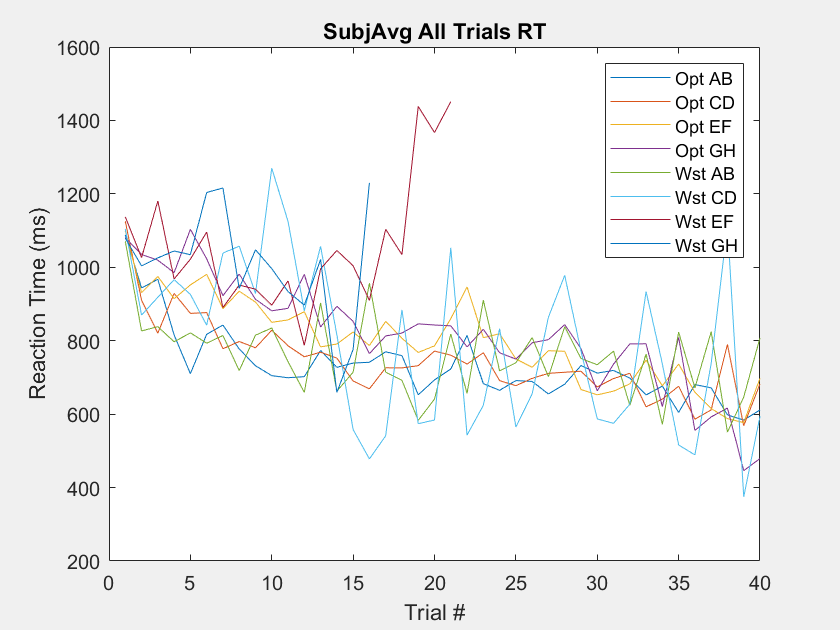

Deci_Backend(Deci);